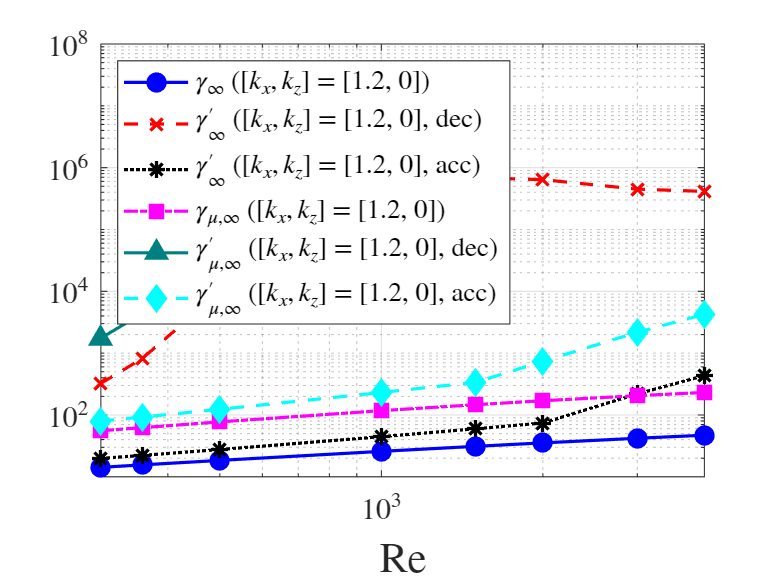

figure('Color', 'w');

% Define line properties
colors  = {'b','r','k','m',[0 0.5 0.5],'c'};
linestyles = {'-','--',':','-.','-','--'};
markers = {'o','x','*','s','^','d'};
markerFaceColors = {'b','r','k','m',[0 0.5 0.5],'c'};

% Plot each dataset
loglog(Re_list, Time_independent_LMI_H_infty_norm_kx_1_2_kz_0, ...
    'Color', colors{1}, 'LineStyle', linestyles{1}, 'Marker', markers{1}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{1});
hold on;
loglog(Re_list, Time_varying_LMI_dec_H_infty_norm_kx_1_2_kz_0, ...
    'Color', colors{2}, 'LineStyle', linestyles{2}, 'Marker', markers{2}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{2});

loglog(Re_list, Time_varying_LMI_acc_H_infty_norm_kx_1_2_kz_0, ...
    'Color', colors{3}, 'LineStyle', linestyles{3}, 'Marker', markers{3}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{3});

loglog(Re_list, Time_independent_LMI_H_mu_infty_norm_kx_1_2_kz_0, ...
    'Color', colors{4}, 'LineStyle', linestyles{4}, 'Marker', markers{4}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{4});

loglog(Re_list, Time_varying_LMI_dec_H_mu_infty_norm_kx_1_2_kz_0, ...
    'Color', colors{5}, 'LineStyle', linestyles{5}, 'Marker', markers{5}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{5});

loglog(Re_list, Time_varying_LMI_acc_H_mu_infty_norm_kx_1_2_kz_0, ...
    'Color', colors{6}, 'LineStyle', linestyles{6}, 'Marker', markers{6}, ...
    'LineWidth', 1.5, 'MarkerSize', 8, 'MarkerFaceColor', markerFaceColors{6});


grid on;
set(gca, 'FontSize', 14, 'TickLabelInterpreter', 'latex');
xlabel('Re', 'Interpreter', 'latex', 'FontSize', 20);
xlim([300 4000]);
ylim([10 1e8]);

legend('$\gamma_\infty$ ($[k_x, k_z$] = [1.2, 0])', ...
       '$\gamma^{\prime}_\infty$ ($[k_x, k_z$] = [1.2, 0], dec)', ...
       '$\gamma^{\prime}_\infty$ ($[k_x, k_z$] = [1.2, 0], acc)', ...
       '$\gamma_{\mu,\infty}$ ($[k_x, k_z$] = [1.2, 0])', ...
       '$\gamma^{\prime}_{\mu,\infty}$ ($[k_x, k_z$] = [1.2, 0], dec)', ...
       '$\gamma^{\prime}_{\mu,\infty}$ ($[k_x, k_z$] = [1.2, 0], acc)', ...
       'Location', 'NorthWest', 'Interpreter', 'latex');


% legend('$\gamma_\infty$ ($[k_x, k_z$] = [1.2, 0])', ...
%        '$\gamma^{\prime}_\infty$ ($[k_x, k_z$] = [1.2, 0], dec)', ...
%        '$\gamma^{\prime}_\infty$ ($[k_x, k_z$] = [1.2, 0], acc)', ...
%        '$\gamma_{\mu,\infty}$ ($[k_x, k_z$] = [1.2, 0])', ...
%        '$\gamma^{\prime}_{\mu,\infty}$ ($[k_x, k_z$] = [1.2, 0], acc)', ...
%        '$\gamma^{\prime}_{\mu,\infty}$ ($[k_x, k_z$] = [1.2, 0], dec)', ...
%        'Location', 'NorthWest', 'Interpreter', 'latex');

% legend('$\gamma_\infty$ ($[k_x, k_z$] = [1, 1])', ...
%        '$\gamma^{\prime}_\infty$ ($[k_x, k_z$] = [1, 1], dec)', ...
%        '$\gamma^{\prime}_\infty$ ($[k_x, k_z$] = [1, 1], acc)', ...
%        '$\gamma_{\mu,\infty}$ ($[k_x, k_z$] = [1, 1])', ...
%        '$\gamma^{\prime}_{\mu,\infty}$ ($[k_x, k_z$] = [1, 1], dec)', ...
%        '$\gamma^{\prime}_{\mu,\infty}$ ($[k_x, k_z$] = [1, 1], acc)', ...
%        'Location', 'NorthWest', 'Interpreter', 'latex');
